## Time-domain analysis

Say, we want not only to examine circuits in the s-domain, but also in the more intuitive time-domain, as is so often the case. ELABorate has built-in functionality for this. Let's start by loading in a simple 1st-order-series-rc-circuit, otherwise known as a low-pass fitler.

circuit = Circuit('circuits/rc_low_pass.txt');
circuit.list

ans =     'Vs 1 0 DC 5
     R1 1 2 10000
     C1 2 0 0.00000001
     '


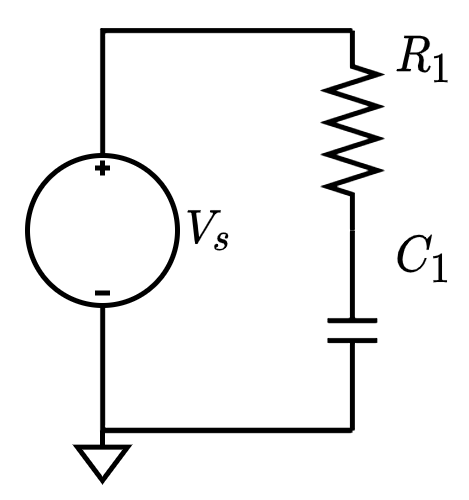

We analyze it as usual to obtain the circuit equations.

ELAB.analyze(circuit)

Symbolic analysis successful (0.202409 sec).


In this case, we have numerical values, so we find the numerical transfer function of the circuit, where the output is the voltage across the capacitor, i.e. from node 1 to node 2.

TF = ELAB.ec2tf(circuit, 1, 2)


Numerical evaluation successful (0.0476673 sec).
Transfer function object created successfully (7.495970e-02 sec).

TF =
 
    10000
  ---------
  s + 10000
 
Continuous-time transfer function.



Say, we want to test how the circuit handles a particular kind of input. In this case, we will have the voltage source input signal be $v_s =10\left(1-e^{-5000t} \right)u\left(t\right)$, where $u\left(t\right)$ is the unit-step function, otherwise known as the *heaviside* function.

syms t
out = ELAB.apply(TF, 10*(1-exp(-5000*t))*heaviside(t))

$$out = \mathrm{heaviside}\left(t\right)\,\left(10\,{\mathrm{e}}^{-10000\,t}-20\,{\mathrm{e}}^{-5000\,t}+10\right)$$

Of course, this can be plotted.

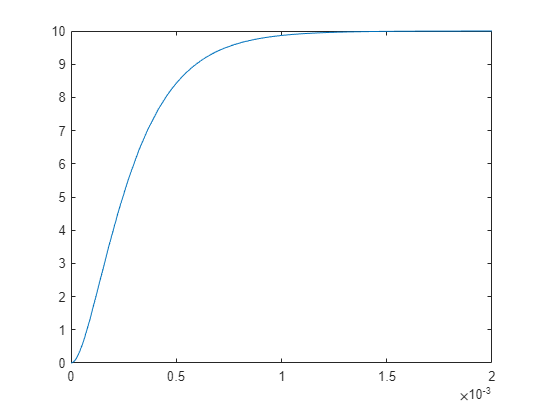

fplot(out, [0,0.002])